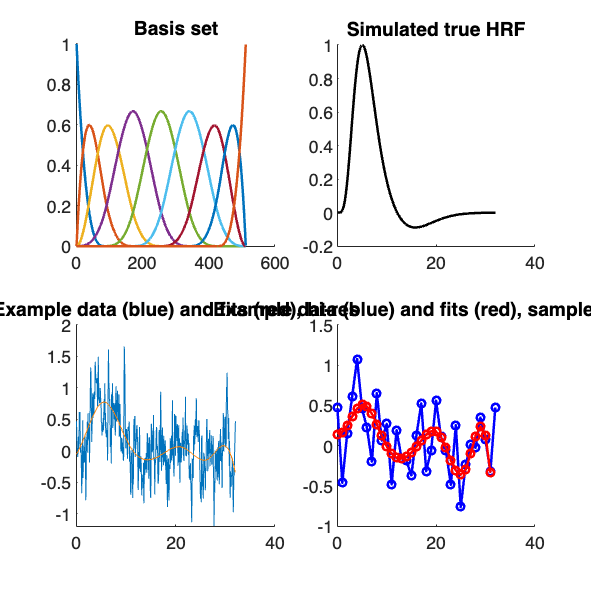



%[xBF_hires, xBF] = fmri_spline_basis(TR, varargin)

[xBF_hires, xBF] = fmri_spline_basis(1, 'plot');

This uses the Bspline function by Tom Nichols:

You can use this to create a spline basis set for a longer time window, e.g., times 1:100 (arbitrary units).

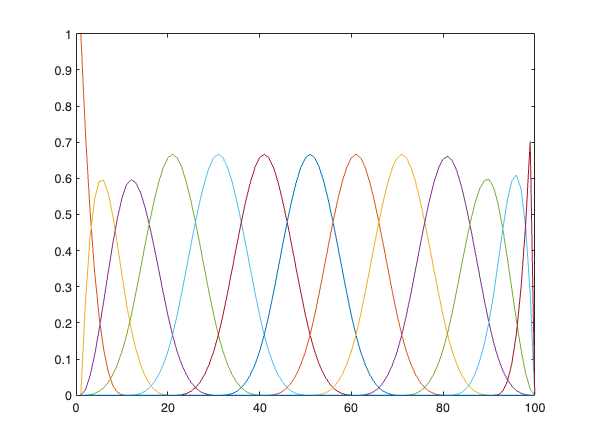

timepoints = 1:100;
order = 4;
knots = [ 1 1 1 1 1:10:100 100 100 100 100 100];
B = Bspline(timepoints, order, knots);
figure; plot(B)

Let's use this to fit a spline to some sample data stored in Matlab:

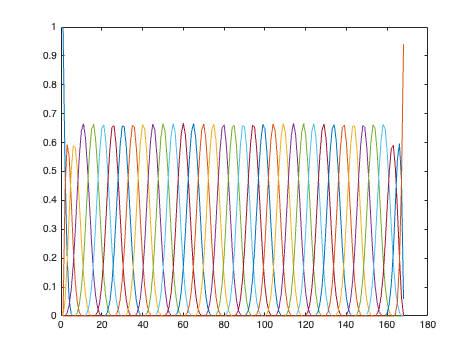


load enso;

% define knots
n_elements = length(month);
nBas = 36; % number of basis functions
knots = [ones(1,order-1) linspace(1,n_elements+0.1,nBas-1) (n_elements+0.1)*ones(1,order-1)];

% create the spline basis. 
B = Bspline(month, order, knots);
figure; plot(B)

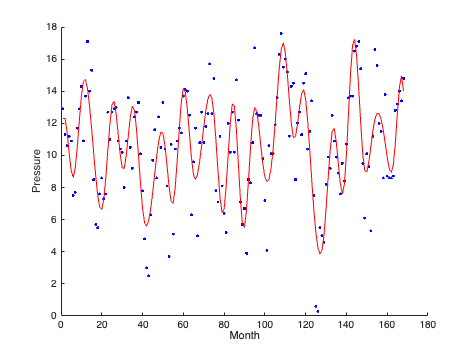


% fit and plot
X = B;            % linear design matrix
X(:, end+1) = 1;
betas = pinv(X) * pressure;
curve = X * betas;

figure; hold on;
plot(month, pressure, 'b.');
plot(month, curve, 'r-')
xlabel('Month');
ylabel('Pressure');

Matlab also has many tools for spline fitting that are very flexible.

The "fit" function fits many kinds of curves and models, and is a great place to start.

More flexible/complex-to-use functions like spaps may also be useful.

The advantage of using Bspline above is that it gives us the basis functions, which we can use to construct our own linear model. Still figuring out how to do that in Matlab.

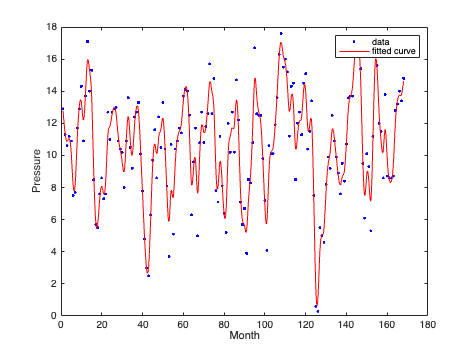

load enso;
[curve, goodness, output] = fit(month,pressure,'smoothingspline');
figure;
plot(curve,month,pressure);
xlabel('Month');
ylabel('Pressure');


% [SP,VALUES] = spaps([10:10:160], [0 0 1 0 0], Inf);
